code adapted from https://www.mathworks.com/help/vision/ug/image-category-classification-using-deep-learning.html

downloadFolder = tempdir;
%change the following line to your image location
imageFolder='\\client\c$\Users\allis\Documents\Comp Apps\Final Project\brain_tumor_dataset'

imageFolder = '\\client\c$\Users\allis\Documents\Comp Apps\Final Project\brain_tumor_dataset'

imds = imageDatastore(imageFolder, 'LabelSource', 'foldernames', 'IncludeSubfolders',true);

tbl = countEachLabel(imds);

% Determine the smallest amount of images in a category
minSetCount = min(tbl{:,2}); 

% Use splitEachLabel method to trim the set.
imds = splitEachLabel(imds, minSetCount, 'randomize');


% Load pretrained network
net = resnet50(); %you have to download this. The instructions are very simple
[trainingSet, testSet] = splitEachLabel(imds, 0.3, 'randomize');
% Create augmentedImageDatastore from training and test sets to resize
% images in imds to the size required by the network.
imageSize = net.Layers(1).InputSize;
augmentedTrainingSet = augmentedImageDatastore(imageSize, trainingSet, 'ColorPreprocessing', 'gray2rgb');
augmentedTestSet = augmentedImageDatastore(imageSize, testSet, 'ColorPreprocessing', 'gray2rgb');

featureLayer = 'fc1000';
trainingFeatures = activations(net, augmentedTrainingSet, featureLayer, ...
    'MiniBatchSize', 32, 'OutputAs', 'columns');

|====================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |       Coding |       Lambda |      Learner |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |              |
|====================================================================================================================|
|    1 | Best   |     0.13793 |      3.3751 |     0.13793 |     0.13793 |     onevsone |   8.5397e-06 |          svm |
|    2 | Best   |     0.12069 |     0.88263 |     0.12069 |     0.12361 |     onevsall |       2.3677 |          svm |
|    3 | Accept |     0.15517 |     0.85675 |     0.12069 |     0.12207 |     onevsall |   5.1002e-07 |          svm |
|    4 | Accept |     0.41379 |      0.8467 |     0.12069 |     0.13906 |     onevsone |      0.58586 |     logistic |
|    5 | Accept |     0.46552 |     0.93045 |   

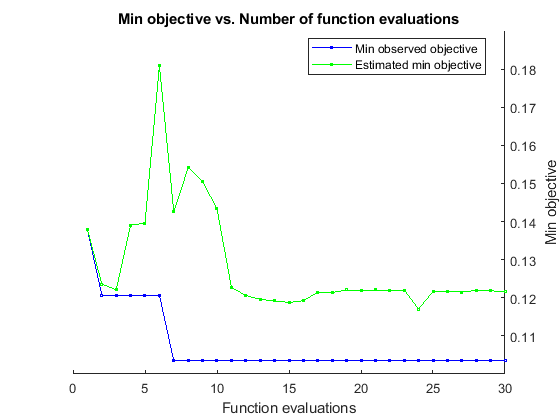


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 95.2643 seconds
Total objective function evaluation time: 20.2783

Best observed feasible point:
     Coding       Lambda      Learner
    ________    __________    _______

    onevsall    1.7273e-07      svm  

Observed objective function value = 0.10345
Estimated objective function value = 0.148
Function evaluation time = 0.78323

Best estimated feasible point (according to models):
     Coding      Lambda      Learner
    ________    _________    _______

    onevsall    0.0028102      svm  

Estimated objective function value = 0.12176
Estimated function evaluation time = 0.62597



% Get training labels from the trainingSet
trainingLabels = trainingSet.Labels;

% Train multiclass SVM classifier using a fast linear solver, and set
% 'ObservationsIn' to 'columns' to match the arrangement used for training
% features.
classifier = fitcecoc(trainingFeatures, trainingLabels, ...
    'Learners', 'Linear', 'Coding', 'onevsall', 'ObservationsIn', 'columns','OptimizeHyperparameters','auto');

% Extract test features using the CNN
testFeatures = activations(net, augmentedTestSet, featureLayer, ...
    'MiniBatchSize', 32, 'OutputAs', 'columns');

% Pass CNN image features to trained classifier
predictedLabels = predict(classifier, testFeatures, 'ObservationsIn', 'columns');

% Get the known labels
testLabels = testSet.Labels;

% Tabulate the results using a confusion matrix.
confMat = confusionmat(testLabels, predictedLabels);

% Convert confusion matrix into percentage form
confMat = bsxfun(@rdivide,confMat,sum(confMat,2))

confMat =     0.7826    0.2174
    0.0870    0.9130


% Display the mean accuracy
mean(diag(confMat))

ans = 0.8478

testImage = readimage(testSet,1);
testLabel = testSet.Labels(1)

testLabel = categorical
     no 


% Create augmentedImageDatastore to automatically resize the image when
% image features are extracted using activations.
ds = augmentedImageDatastore(imageSize, testImage, 'ColorPreprocessing', 'gray2rgb');

% Extract image features using the CNN
imageFeatures = activations(net, ds, featureLayer, 'OutputAs', 'columns');

% Make a prediction using the classifier
predictedLabel = predict(classifier, imageFeatures, 'ObservationsIn', 'columns')

predictedLabel = categorical
     no 
